## **Taller: métodos no paramétricos de identificación**

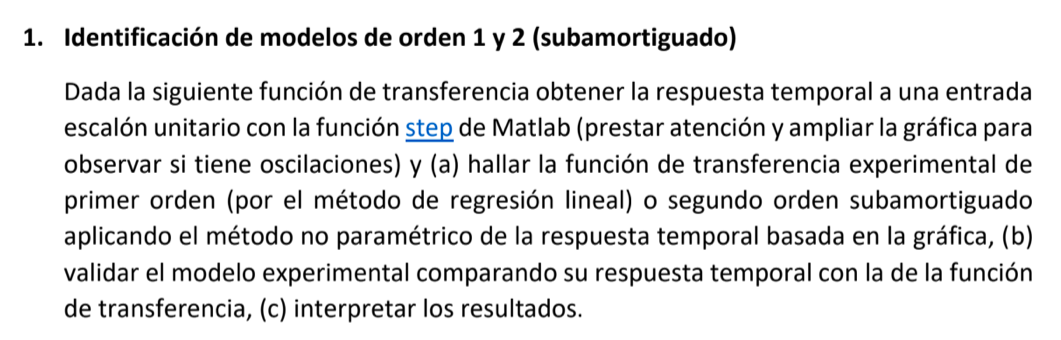

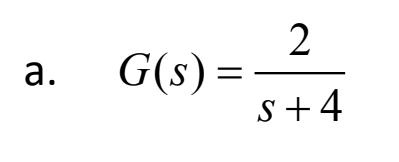

%función de transferencia
G1 = tf(2,[1 4])

G1 =
 
    2
  -----
  s + 4
 
Continuous-time transfer function.



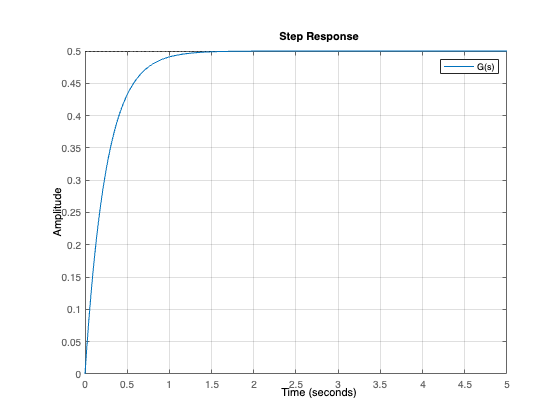

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 5;
figure(1)
clf
step(G1,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G1,tiempofinal);
inicio = find(y > 0, 1);%identificamos el dato a partir del cual el modelo responde a la entrada
yvalores = y(inicio:end);
tvalores = t(inicio:end);
k = yvalores(end)-y(1); %valor de k según la fórmula

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k+eps)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tfEstimada =
 
                       0.5
  exp(-0.0645*s) * ------------
                   0.2402 s + 1
 
Continuous-time transfer function.



*b) Validación*

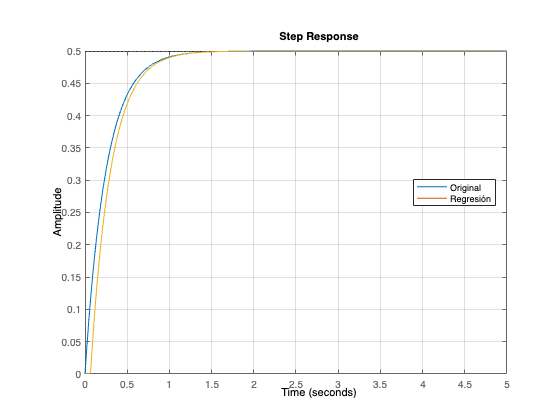

figure(1)
hold on
step(tfEstimada)
legend({'Original','Regresión'},'Location','best')

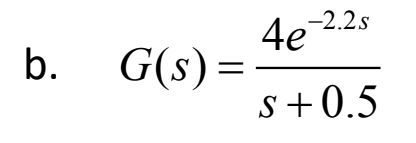

%función de transferencia
G2 = zpk([],[-0.5],4,'InputDelay',2.2)

G2 =
 
                   4
  exp(-2.2*s) * -------
                (s+0.5)
 
Continuous-time zero/pole/gain model.



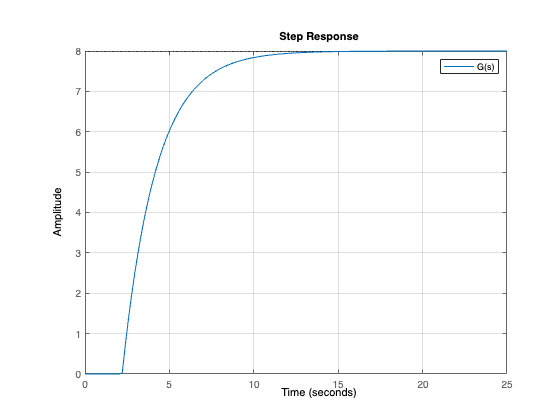

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 25;
figure(2)
clf
step(G2,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G2,tiempofinal)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


t =          0
    0.1838
    0.3676
    0.5515
    0.7353
    0.9191
    1.1029
    1.2868
    1.4706
    1.6544


inicio = find(y > 0, 1)%identificamos el dato a partir del cual el modelo responde a la entrada

inicio = 13

yvalores = y(inicio:end)

yvalores =     0.0235
    0.7239
    1.3629
    1.9457
    2.4774
    2.9623
    3.4047
    3.8083
    4.1763
    4.5121


tvalores = t(inicio:end)

tvalores =     2.2059
    2.3897
    2.5735
    2.7574
    2.9412
    3.1250
    3.3088
    3.4926
    3.6765
    3.8603


k = yvalores(end)-y(1) %valor de k según la fórmula

k = 7.9999

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k+eps)),1)%regresión lineal al logaritmo de y

p =    NaN   NaN


s = struct with fields:
        R: [2×2 double]
       df: 123
    normr: NaN


T = -1/p(1)

T = NaN

tau = -p(2)/p(1)%valores de parámetros  T y tau según las fórmulas

tau = NaN

tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

Error using tf
The "InputDelay" property must be set to a vector of real finite numbers.

*b) Validación*

figure(2)
hold on
step(tfEstimada)
legend({'Original','Regresión'},'Location','best')


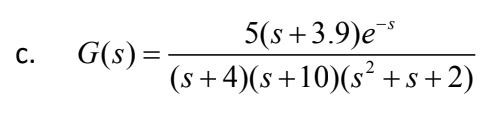

syms s
f1 = s^2+s+2;
factor(f1, 'FactorMode', 'complex')

$$ans = \left(\begin{array}{cc} s+0.5+1.3228756555322952952508078768196\,\mathrm{i} & s+0.5-1.3228756555322952952508078768196\,\mathrm{i} \end{array}\right)$$

%función de transferencia
G3 = zpk([-3.9],[-4, -10, -(0.5 + 1.32287*i),-( 0.5-1.32287*i)],5,'InputDelay',1)

G3 =
 
                      5 (s+3.9)
  exp(-1*s) * --------------------------
              (s+4) (s+10) (s^2 + s + 2)
 
Continuous-time zero/pole/gain model.



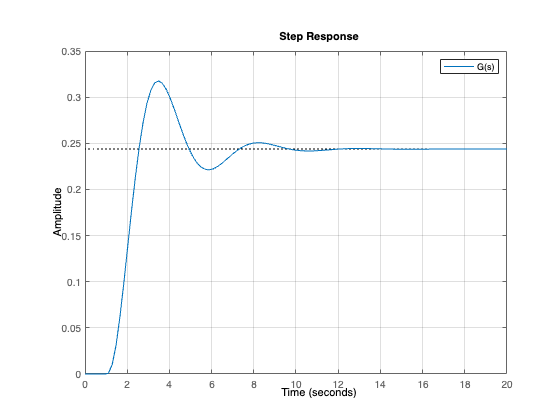

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 20;
figure(3)
clf
step(G3,tiempofinal)
grid on
legend({'G(s)'})

*a) Ajuste modelo segundo orden*

[y,t] = step(G3);%recolección de datos por recomendación de MatLab
inicio = find(y > 0, 1);%dato a partir del cual el sistema reacciona
tau = t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 1.0131

deltaY = y(end) - y(1)%delta de y por definición

deltaY = 0.2430

Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.6371

omega0 = pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.6389

tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                        0.6527
  exp(-1.01*s) * ---------------------
                 s^2 + 2.088 s + 2.686
 
Continuous-time transfer function.



*b) Validación*

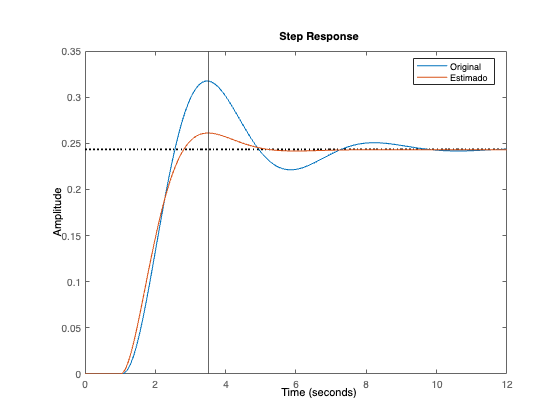

figure(3)
clf
step(G3)
hold on
step(tfEstimada)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

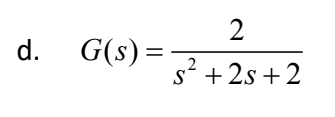

syms s
f1 = s^2+2*s+2;
factor(f1, 'FactorMode', 'complex')

$$ans = \left(\begin{array}{cc} s+1.0+1.0\,\mathrm{i} & s+1.0-1.0\,\mathrm{i} \end{array}\right)$$

%función de transferencia
G4 = zpk([ ],[-(1 + 1*i),-( 1-1*i)],2)

G4 =
 
        2
  --------------
  (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



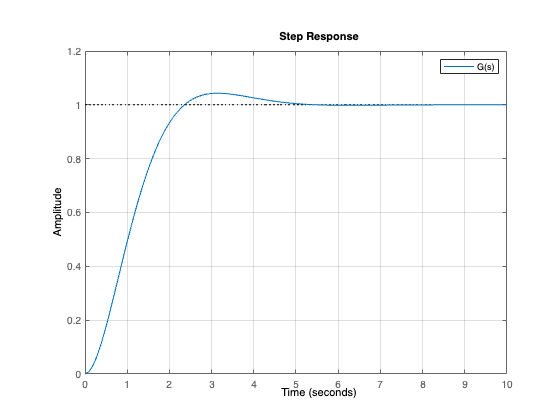

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 10;
figure(4)
clf
step(G4,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G4);%recolección de datos por recomendación de MatLab
inicio = find(y > 0, 1);%dato a partir del cual el sistema reacciona
tau = t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 0.0461

deltaY = y(end) - y(1)%delta de y por definición

deltaY = 0.9981

Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.7023

omega0 = pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.4303

tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                           2.042
  exp(-0.0461*s) * ---------------------
                   s^2 + 2.009 s + 2.046
 
Continuous-time transfer function.



*b) Validación*

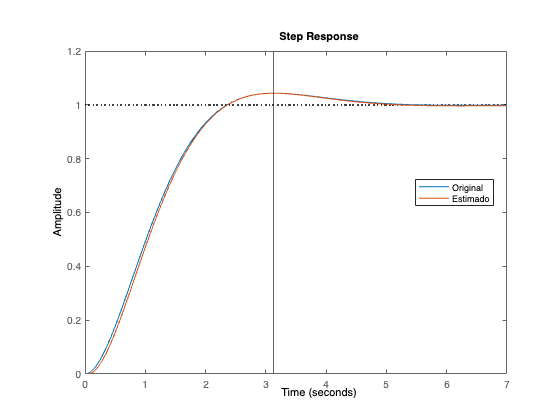

figure(4)
clf
step(G4)
hold on
step(tfEstimada)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

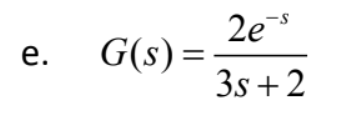


syms s
f1 = 3*s+2;
factor(f1, 'FactorMode', 'complex')

$$ans = \left(\begin{array}{cc} 3.0 & s+0.66666666666666666666666666666667 \end{array}\right)$$

%función de transferencia
G5 = zpk([ ],[-0.66666],(2*1/3),'InputDelay',1)

G5 =
 
               0.66667
  exp(-1*s) * ----------
              (s+0.6667)
 
Continuous-time zero/pole/gain model.



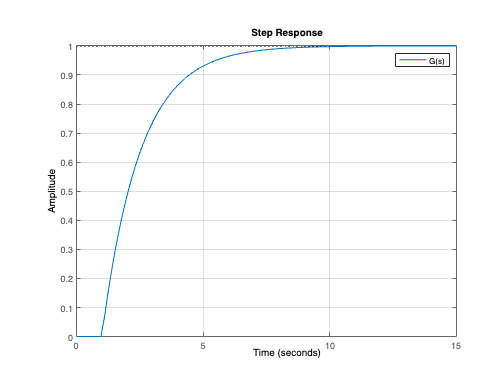

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 15;
clf
figure(5)
step(G5,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G5,tiempofinal);
inicio = find(y > 0, 1);%identificamos el dato a partir del cual el modelo responde a la entrada
yvalores = y(inicio:end);
tvalores = t(inicio:end);
k = yvalores(end)-y(1); %valor de k según la fórmula

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k+eps)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tfEstimada =
 
                  0.9999
  exp(-1.9*s) * -----------
                1.203 s + 1
 
Continuous-time transfer function.



*b) Validación*

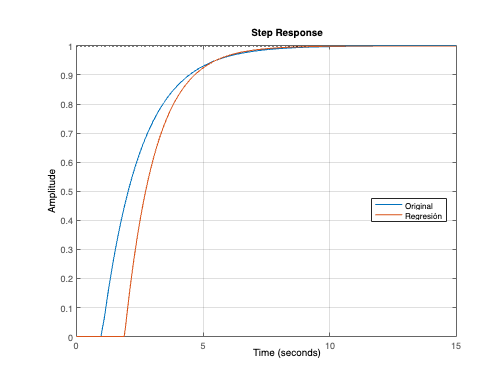

figure(5)
hold on
step(tfEstimada)
legend({'Original','Regresión'},'Location','best')

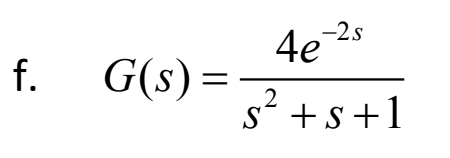

syms s
f1 = s^2+s+2;
factor(f1, 'FactorMode', 'complex')

$$ans = \left(\begin{array}{cc} s+0.5+1.3228756555322952952508078768196\,\mathrm{i} & s+0.5-1.3228756555322952952508078768196\,\mathrm{i} \end{array}\right)$$

%función de transferencia
G6 = zpk([ ],[-(0.5 + 1.32287*i),-( 0.5-1.32287*i)],4, 'InputDelay',2)

G6 =
 
                    4
  exp(-2*s) * -------------
              (s^2 + s + 2)
 
Continuous-time zero/pole/gain model.



%respuesta temporal a una entrada de escalón unitario
tiempofinal = 15;
clf
figure(6)
step(G6,tiempofinal)
grid on
legend({'G(s)'})

*a) Ajuste modelo segundo orden*

[y,t] = step(G6);%recolección de datos por recomendación de MatLab
inicio = find(y > 0, 1);%dato a partir del cual el sistema reacciona
tau = t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 2.0263

deltaY = y(end) - y(1)%delta de y por definición

deltaY = 1.9967

Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.1544

omega0 = pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.3278

tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                          3.52
  exp(-2.03*s) * ----------------------
                 s^2 + 0.4101 s + 1.763
 
Continuous-time transfer function.



*b) Validación*

figure(6)
clf
step(G6)
hold on
step(tfEstimada)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

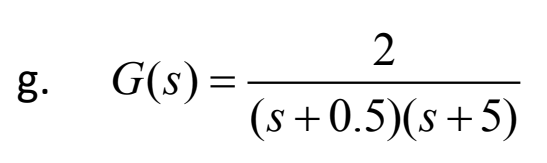

%función de transferencia
G7 = zpk([],[-0.5 -5],2)

G7 =
 
        2
  -------------
  (s+0.5) (s+5)
 
Continuous-time zero/pole/gain model.



%respuesta temporal a una entrada de escalón unitario
tiempofinal = 20;
clf
figure(7)
step(G7,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G7,tiempofinal);
inicio = find(y > 0, 1);%identificamos el dato a partir del cual el modelo responde a la entrada
yvalores = y(inicio:end);
tvalores = t(inicio:end);
k = yvalores(end)-y(1); %valor de k según la fórmula

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k+eps)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tfEstimada =
 
                      0.8
  exp(-0.729*s) * -----------
                  1.825 s + 1
 
Continuous-time transfer function.



*b) Validación*

figure(7)
hold on
step(tfEstimada)
legend({'Original','Regresión'},'Location','best')

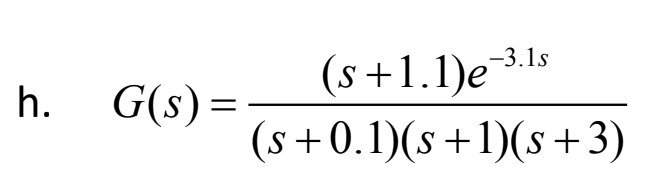

%función de transferencia
G8 = zpk([-1.1],[-0.1 -1 -3],1,'InputDelay', 3.1)

G8 =
 
                      (s+1.1)
  exp(-3.1*s) * -------------------
                (s+0.1) (s+1) (s+3)
 
Continuous-time zero/pole/gain model.



%respuesta temporal a una entrada de escalón unitario
tiempofinal = 80;
clf
figure(8)
step(G8,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G8,tiempofinal);
inicio = find(y > 0, 1);%identificamos el dato a partir del cual el modelo responde a la entrada
yvalores = y(inicio:end);
tvalores = t(inicio:end);
k = yvalores(end)-y(1); %valor de k según la fórmula

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k+eps)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

Error using tf
The "InputDelay" property must be set to a vector of real finite numbers.

*b) Validación*

figure(8)
hold on
step(tfEstimada)
legend({'Original','Regresión'},'Location','best')

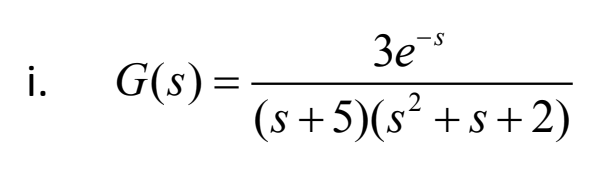

%función de transferencia
G9 = zpk([],[-5,-(0.5 + 1.32287*i),-( 0.5-1.32287*i)],3,'InputDelay', 1)

G9 =
 
                       3
  exp(-1*s) * -------------------
              (s+5) (s^2 + s + 2)
 
Continuous-time zero/pole/gain model.



%respuesta temporal a una entrada de escalón unitario
tiempofinal = 25;
clf
figure(9)
step(G9,tiempofinal)
grid on
legend({'G(s)'})

*a) Ajuste modelo segundo orden*

[y,t] = step(G9);%recolección de datos por recomendación de MatLab
inicio = find(y > 0, 1);%dato a partir del cual el sistema reacciona
tau = t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 1.0131

deltaY = y(end) - y(1)%delta de y por definición

deltaY = 0.2988

Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.6106

omega0 = pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.5383

tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                        0.7071
  exp(-1.01*s) * ---------------------
                 s^2 + 1.879 s + 2.366
 
Continuous-time transfer function.



*b) Validación*

figure(9)
clf
step(G9)
hold on
step(tfEstimada)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

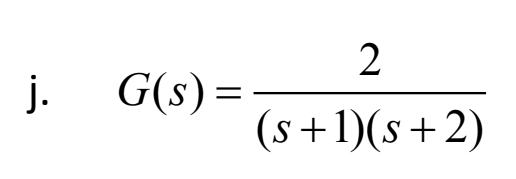

%función de transferencia
G10 = zpk([],[-1 -2],2)

G10 =
 
       2
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



%respuesta temporal a una entrada de escalón unitario
tiempofinal = 15;
clf
figure(10)
step(G10,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G10,tiempofinal);
inicio = find(y > 0, 1);%identificamos el dato a partir del cual el modelo responde a la entrada
yvalores = y(inicio:end);
tvalores = t(inicio:end);
k = yvalores(end)-y(1); %valor de k según la fórmula

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k+eps)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tfEstimada =
 
                      1
  exp(-0.82*s) * ------------
                 0.9526 s + 1
 
Continuous-time transfer function.



*b) Validación*

figure(10)
hold on
step(tfEstimada)
legend({'Original','Regresión'},'Location','best')

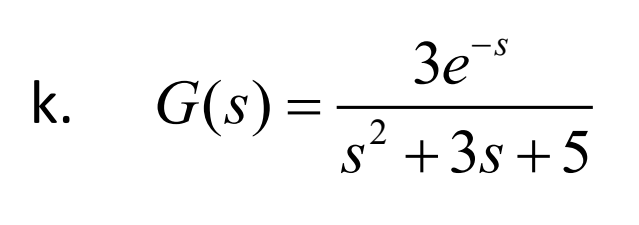

syms s
f1 = s^2+3*s+5;
factor(f1, 'FactorMode', 'complex')

$$ans = \left(\begin{array}{cc} s+1.5+1.6583123951776999245574663683353\,\mathrm{i} & s+1.5-1.6583123951776999245574663683353\,\mathrm{i} \end{array}\right)$$

%función de transferencia
G11 = zpk([],[-(1.5 + 1.6583*i),-(1.5 - 1.6583*i)],3, 'InputDelay', 1)

G11 =
 
                    3
  exp(-1*s) * --------------
              (s^2 + 3s + 5)
 
Continuous-time zero/pole/gain model.



%respuesta temporal a una entrada de escalón unitario
tiempofinal = 10;
clf
figure(11)
step(G11,tiempofinal)
grid on
legend({'G(s)'})

*a) Ajuste modelo segundo orden*

[y,t] = step(G11);%recolección de datos por recomendación de MatLab
inicio = find(y > 0, 1);%dato a partir del cual el sistema reacciona
tau = t(inicio);%tiempo a partir del cual el sistema reacciona
deltaY = y(end) - y(1);%delta de y por definición
Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2);%valor de z (Soderstrom)
omega0 = pi/(Tp*sqrt(1-zeta^2));%valor de omega0 por fórmulas
tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                         3.562
  exp(-1.01*s) * ---------------------
                 s^2 + 3.541 s + 5.949
 
Continuous-time transfer function.



*b) Validación*

figure(11)
clf
step(G11)
hold on
step(tfEstimada)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

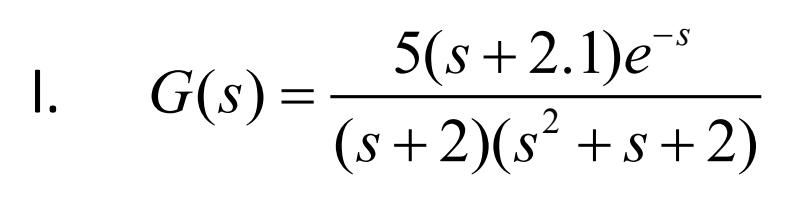

%función de transferencia
G12 = zpk([-2.1],[-2,-(0.5 + 1.32287*i),-( 0.5-1.32287*i)],5,'InputDelay', 1)

G12 =
 
                   5 (s+2.1)
  exp(-1*s) * -------------------
              (s+2) (s^2 + s + 2)
 
Continuous-time zero/pole/gain model.



%respuesta temporal a una entrada de escalón unitario
tiempofinal = 20;
clf
figure(12)
step(G12,tiempofinal)
grid on
legend({'G(s)'})

*a) Ajuste modelo segundo orden*

[y,t] = step(G12);%recolección de datos por recomendación de MatLab
inicio = find(y > 0, 1);%dato a partir del cual el sistema reacciona
tau = t(inicio);%tiempo a partir del cual el sistema reacciona
deltaY = y(end) - y(1);%delta de y por definición
Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2);%valor de z (Soderstrom)
omega0 = pi/(Tp*sqrt(1-zeta^2));%valor de omega0 por fórmulas
tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                         4.532
  exp(-1.01*s) * ----------------------
                 s^2 + 0.1989 s + 1.731
 
Continuous-time transfer function.



*b) Validación*

figure(12)
clf
step(G12)
hold on
step(tfEstimada)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

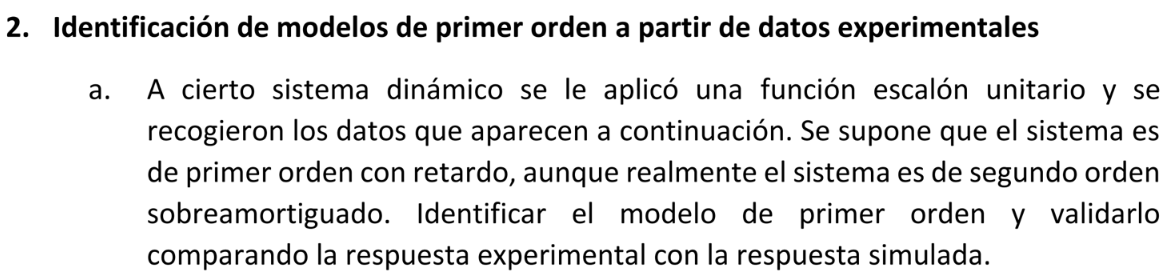

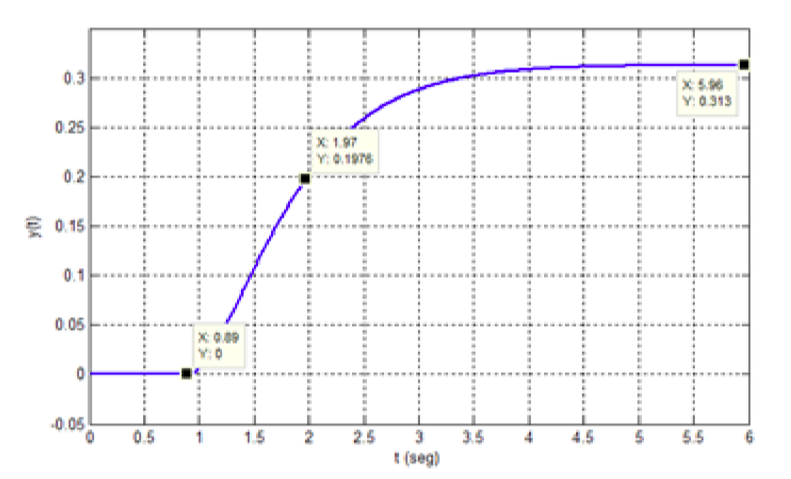

*Método gráfico de primer orden*

tau = 0.89;%primer valor donde y reacciona a la entrada
valT = 1.97;%posición donde y alcanza el 63.2% de su valor final
T = 1.97 - tau;%valor de T por definición
k = 0.313;
A = 1;
tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tfEstimada =
 
                   0.313
  exp(-0.89*s) * ----------
                 1.08 s + 1
 
Continuous-time transfer function.



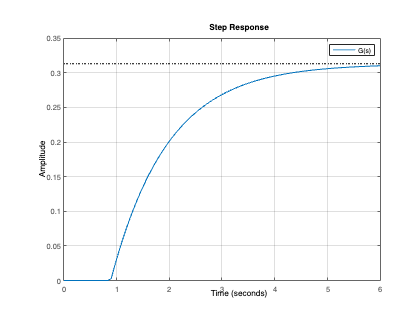


tiempofinal = 6;
clf
figure(13)
step(tfEstimada,tiempofinal)
grid on
legend({'G(s)'})

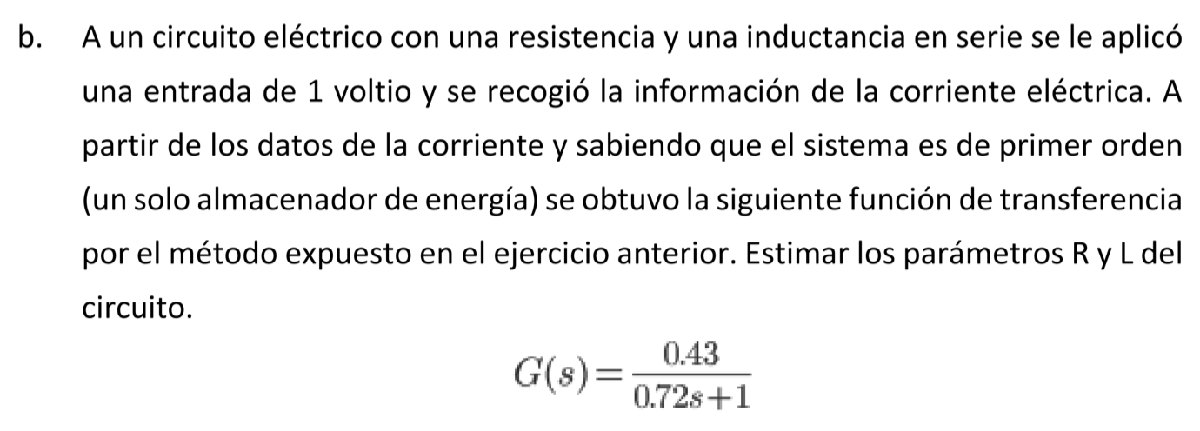

G = zpk([],[-1/0.72],0.43/0.72)

G =
 
   0.59722
  ---------
  (s+1.389)
 
Continuous-time zero/pole/gain model.



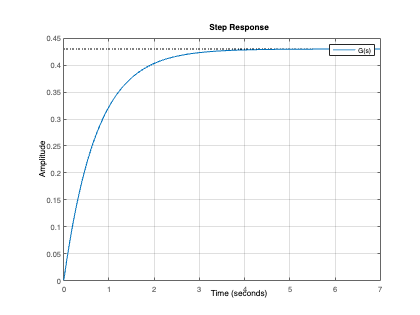


tiempofinal = 7;
clf
figure(14)
step(G,tiempofinal)
grid on
legend({'G(s)'})

Revisar diapositivas.

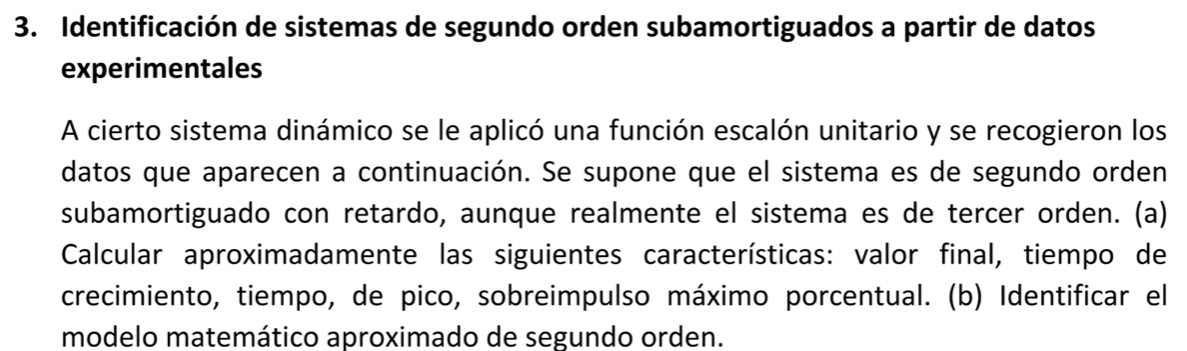

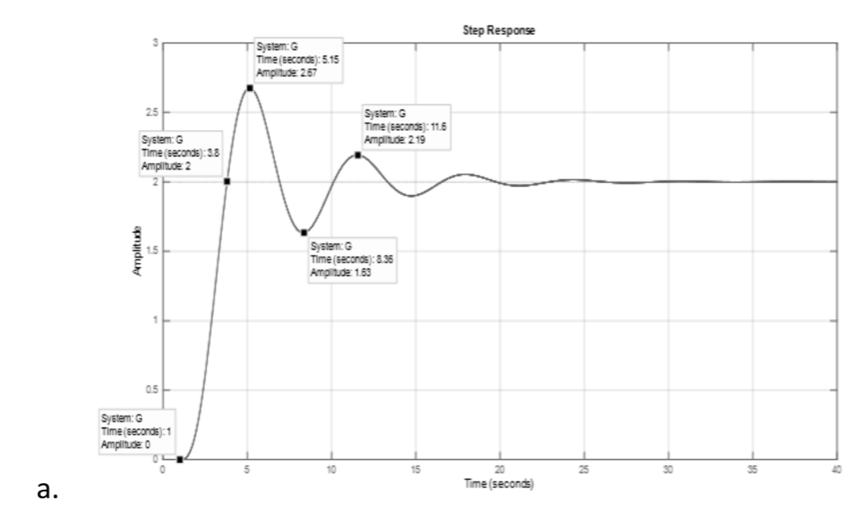

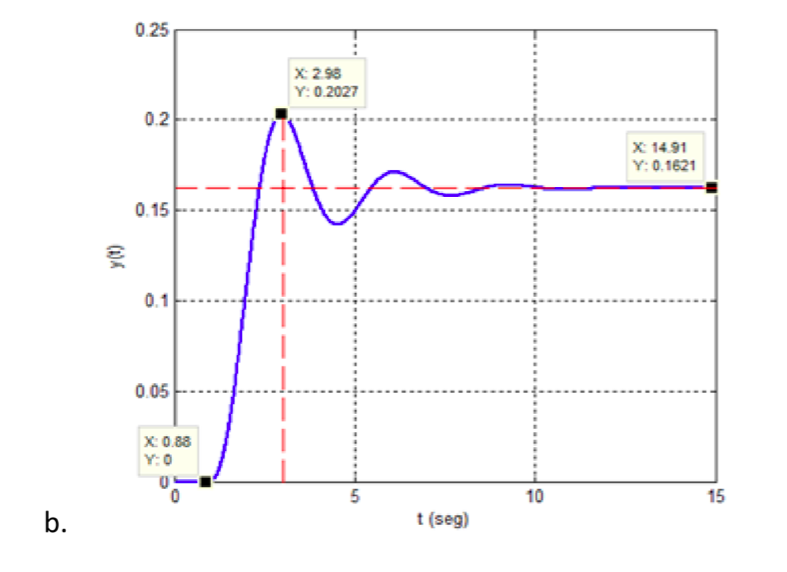

*Ajuste modelo segundo orden*

tau = 0.88;%tiempo a partir del cual el sistema reacciona
deltaY = 0.1621 - 0;%delta de y por definición
Mp = 0.2027 - 0.1621;%sobreimpulso máximo pode definición
Tp = 2.98 - tau;%tiempo de pico, se le debe restar el retardo
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.7140

Como 0<zeta<1, sistema es subamortiguado

omega0 = pi/(Tp*sqrt(1-zeta^2));%valor de omega0 por fórmulas
tfEstimada = tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                        0.7401
  exp(-0.88*s) * ---------------------
                 s^2 + 3.051 s + 4.566
 
Continuous-time transfer function.



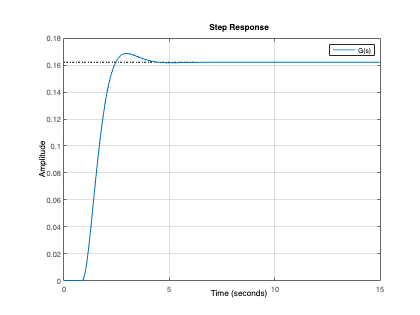

tiempofinal = 15;
clf
figure(15)
step(tfEstimada,tiempofinal)
grid on
legend({'G(s)'})

En las funciones en general aparecen muchos numeritos, muchos calculos numericos, lleva a propagacion del error

Intentar usar los dos valores de zeta segun cual funciona mejor.

Esto no se parece ni mierda, pero con zeta =0.4 si, por que?

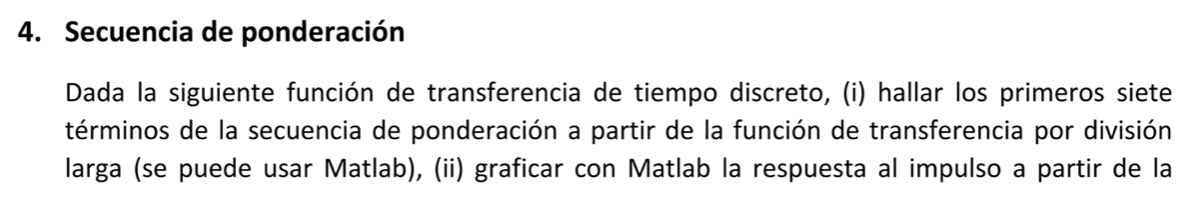

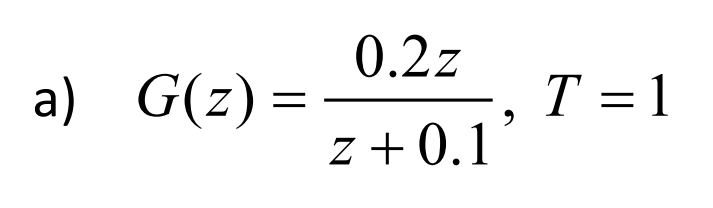

% sample time? T?

num = [0.2 0];
den = [1 0.1];
Ga = tf(num,den,1)

Ga =
 
   0.2 z
  -------
  z + 0.1
 
Sample time: 1 seconds
Discrete-time transfer function.



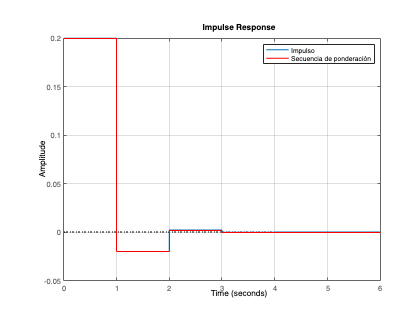

L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(Ga,0:1:L-1); %impulso
hold on
stairs(0:1:L-1, Secuencia,'r')
grid on
legend({'Impulso','Secuencia de ponderación'})

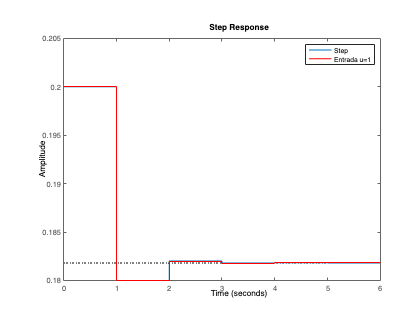

clf
step(Ga,0:1:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:1:L-1, respuesta, 'r')
legend({'Step','Entrada u=1'})

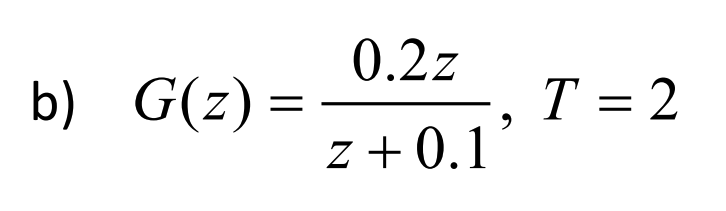

num = [0.2 0];
den = [1 0.1];
Gb = tf(num,den,1)

Gb =
 
   0.2 z
  -------
  z + 0.1
 
Sample time: 1 seconds
Discrete-time transfer function.



L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(Gb,0:1:L-1); %impulso
hold on
stairs(0:1:L-1, Secuencia,'r')
grid on
legend({'Impulso','Secuencia de ponderación'})

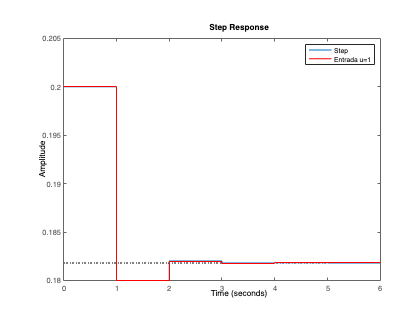

clf
step(Gb,0:1:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:1:L-1, respuesta, 'r')
legend({'Step','Entrada u=1'})

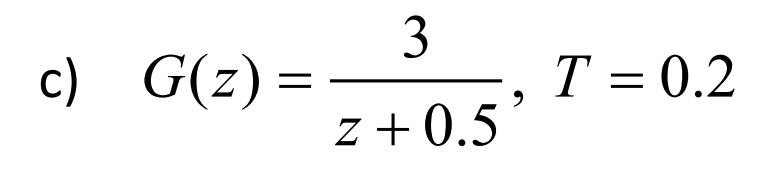

T = 1;
num = [3];
den = [1 0.5];
Gc = tf(num,den,T)

Gc =
 
     3
  -------
  z + 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.



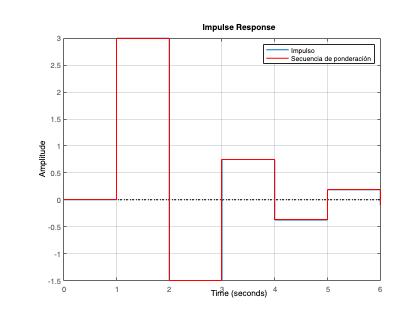

L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(Gc,0:T:L-1); %impulso
hold on
stairs(0:T:L-1, Secuencia,'r')
grid on
legend({'Impulso','Secuencia de ponderación'})

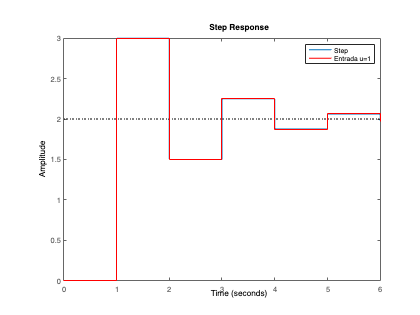

clf
step(Gc,0:T:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:T:L-1, respuesta, 'r')
legend({'Step','Entrada u=1'})

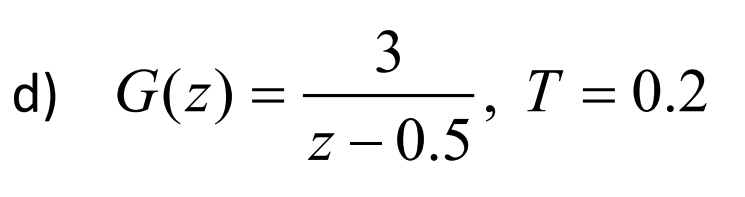

num = [3];
den = [1 -0.5];
Gd = tf(num,den,1)

Gd =
 
     3
  -------
  z - 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.



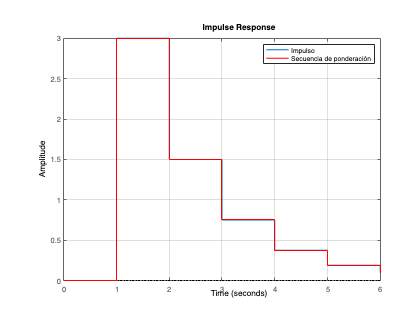

L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(Gd,0:1:L-1); %impulso
hold on
stairs(0:1:L-1, Secuencia,'r')
grid on
legend({'Impulso','Secuencia de ponderación'})

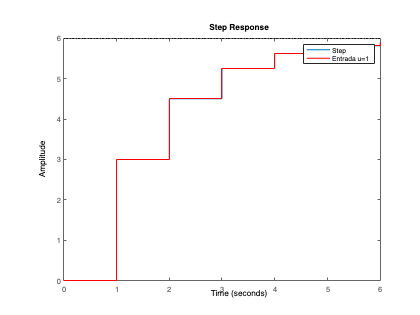

clf
step(Gd,0:1:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:1:L-1, respuesta, 'r')
legend({'Step','Entrada u=1'})

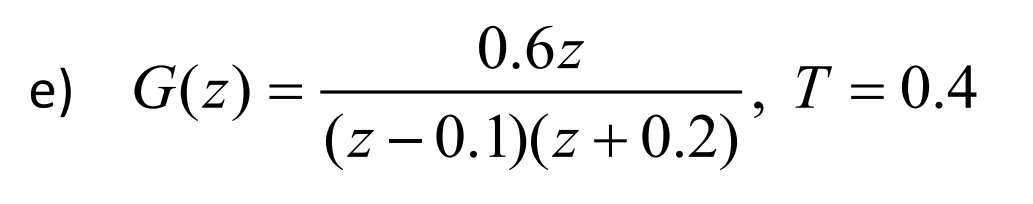

num = [0.6 0];
den = [1 0.1 -0.02];
Ge = tf(num,den,1)

Ge =
 
        0.6 z
  ------------------
  z^2 + 0.1 z - 0.02
 
Sample time: 1 seconds
Discrete-time transfer function.



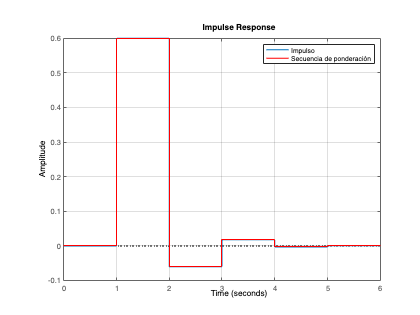

L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(Ge,0:1:L-1); %impulso
hold on
stairs(0:1:L-1, Secuencia,'r')
grid on
legend({'Impulso','Secuencia de ponderación'})

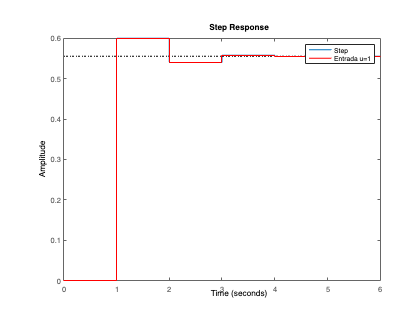

clf
step(Ge,0:1:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:1:L-1, respuesta, 'r')
legend({'Step','Entrada u=1'})

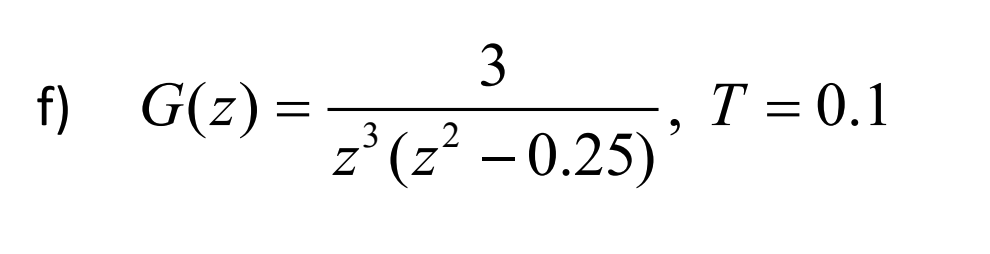

num = [3];
den = [1 0 -0.25 0 0 0];
Gf = tf(num,den,1)

Gf =
 
        3
  --------------
  z^5 - 0.25 z^3
 
Sample time: 1 seconds
Discrete-time transfer function.



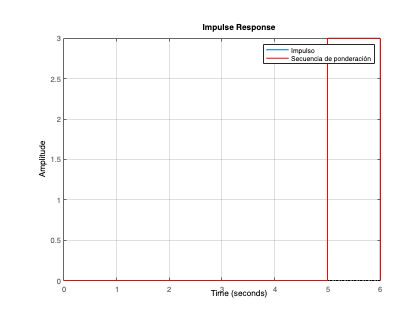

L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(Gf,0:1:L-1); %impulso
hold on
stairs(0:1:L-1, Secuencia,'r')
grid on
legend({'Impulso','Secuencia de ponderación'})

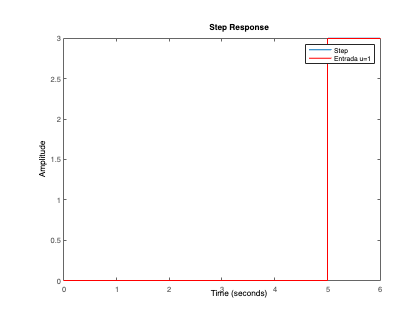

clf
step(Gf,0:1:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:1:L-1, respuesta, 'r')
legend({'Step','Entrada u=1'})

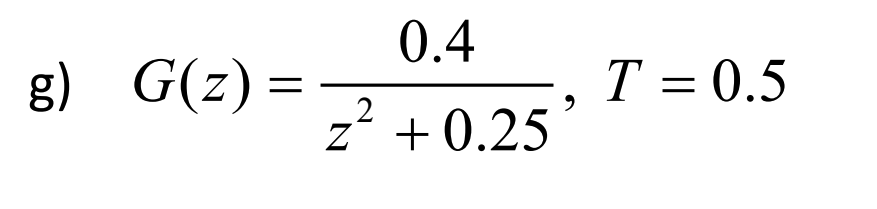

num = [0.4];
den = [1 0 0.25];
Gg = tf(num,den,1)

Gg =
 
     0.4
  ----------
  z^2 + 0.25
 
Sample time: 1 seconds
Discrete-time transfer function.



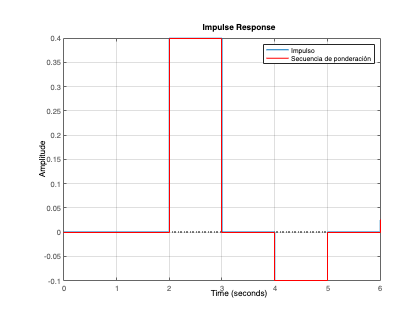

L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(Gg,0:1:L-1); %impulso
hold on
stairs(0:1:L-1, Secuencia,'r')
grid on
legend({'Impulso','Secuencia de ponderación'})

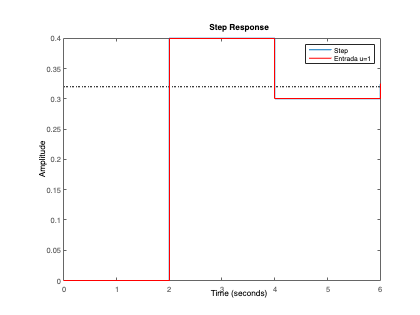

clf
step(Gg,0:1:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:1:L-1, respuesta, 'r')
legend({'Step','Entrada u=1'})

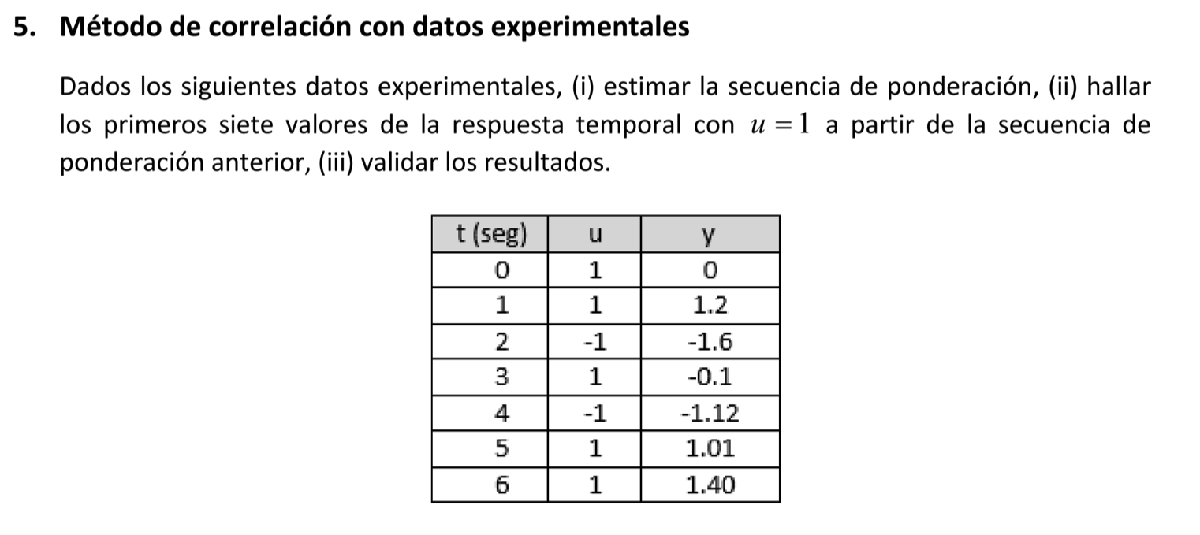

t = 0:1:6;

Unrecognized function or variable 'den'.

u = [1,1,-1,1,-1,1,1];
y = [0,1.2,-1.6,-0.1,-1.12,1.01,1.4];
M = 7;
N = 1;
[cyu,lagsyu] = xcorr(y,u,M-1);%M elementos de la correlación entre y y u
[cu,lagsu] = xcorr(u,0);%correlación de la entrada con ella misma en el instante 0
tf_est=cyu(lagsyu>=0)./(N:-1:N-M+1)'/(cu/N);%fórmula para la secuencia de ponderación
delay=length(den)-length(num);%cálculo del retardo del sistema
tf_real=ldiv([1],[1 0.5],M-delay);%cálculo de la secuencia de ponderación
tf_real=[zeros(1,delay) tf_real];%adición del retardo a la secuencia de ponderación
figure(2)
clf
stem(lagsyu,cyu)%gráfica de la correlación de y y u
title('R_{yu}(\tau)')
pdata=0:1:M-1;
figure(3)
clf
subplot(2,1,1)
stem(pdata,tf_est)%secuencia estimada
title('Estimado')
subplot(2,1,2)
stem(pdata,tf_real)%secuencia real
title('Real')
data = iddata(y,u');%datos para usar las funciones mejoradas de MatLab
sys = impulseest(data,M);%secuencia de ponderación estimada por MatLab
figure(4)
clf
subplot(2,1,1)
h = impulseplot(sys);%secuencia de ponderación estimada por MatLab
subplot(2,1,2)
stem(pdata,tf_real)%secuencia real
title('Real')